% Simulation code for paper "A unified framework for perceived magnitude
% and discriminability of sensory stimuli

% Here, we are going to simulate 2 examples.

% In the first example, we simulate Weber's law and power-law percept. 
% In the second example, we simulate threshold and intensity in a more
% generalized range. 


## Example parameters

% Example 1
 s = linspace(20, 100, 50);
 d = 4.0225;
 w = 1./0.0631;
 beta = 1.1978;
 g = 1;
 c = 10;
 sc = .1;
 nl1 = .1;
 nl2 = 0.01;


## Generate threshold ground truth and data

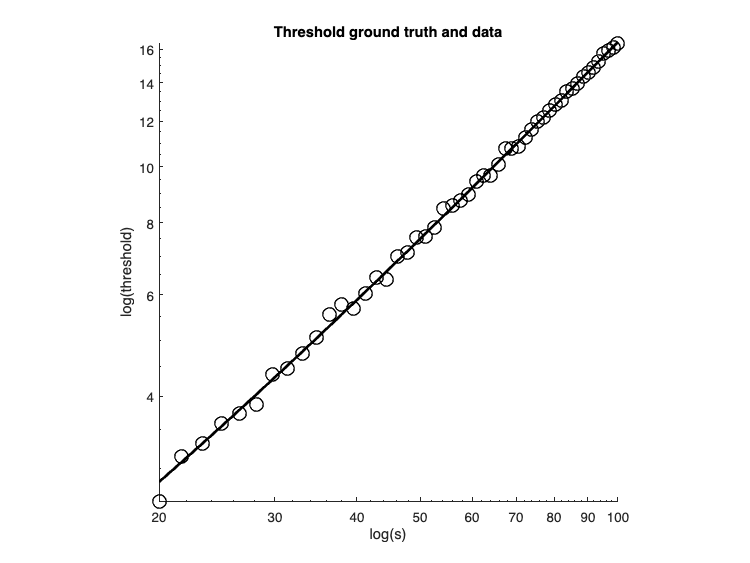

% Generating ground truth and data using Equation 4 in the main text
mk_threshold = @(s, w, d, beta) ((s + d).^beta)./w; 

% make ground truth
threshold_gt = mk_threshold(s, w, d, beta);
% adding noise to generate data
threshold_dt = threshold_gt + normrnd(0, nl1, size(s));

figure (1), clf, 
loglog(s, threshold_gt, 'k-', 'linewidth', 2), hold on
loglog(s, threshold_dt, 'ko', 'markersize', 10, 'linewidth', 1), axis square
title('Threshold ground truth and data'), box off, xlabel('log(s)'), ylabel('log(threshold)')

## Generate intensity ground truth

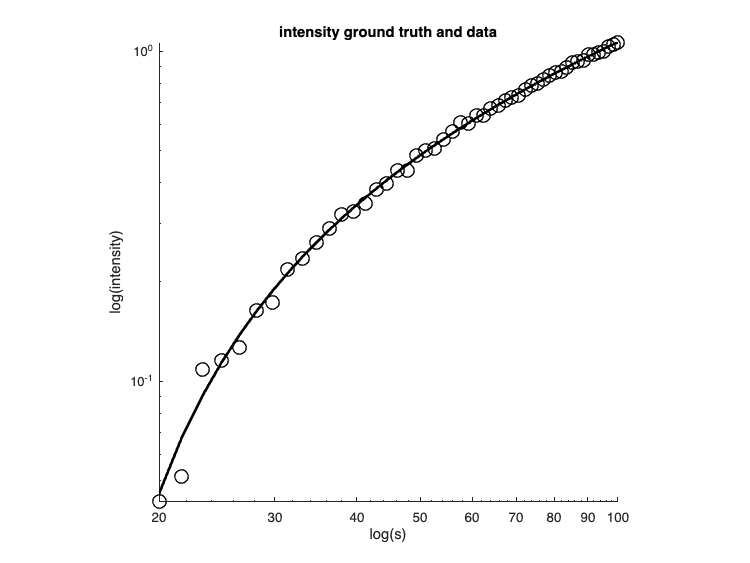

% generate ground truth intensity using a combination of threshold ground
% truth and modulated Poisosn noise
intensity_gt = mkPercept(s, d, w, beta, c, g, sc);

% generate intensity data by adding Gaussian noise to ground truth
intensity_dt = intensity_gt + normrnd(0, nl2, size(s));

figure (2), clf
loglog(s, intensity_gt, 'k-', 'linewidth', 2), axis square, hold on
loglog(s, intensity_dt, 'ko', 'markersize', 10, 'linewidth', 1), 
title('intensity ground truth and data'), box off, xlabel('log(s)'), ylabel('log(intensity)'), box off

## prep for model fitting

f = []; 

n_repeats = 100; % Repeatedly fitting the intensity data using different models with different seeds, so that we can choose the best fitting outcome

## Fitting threshold data

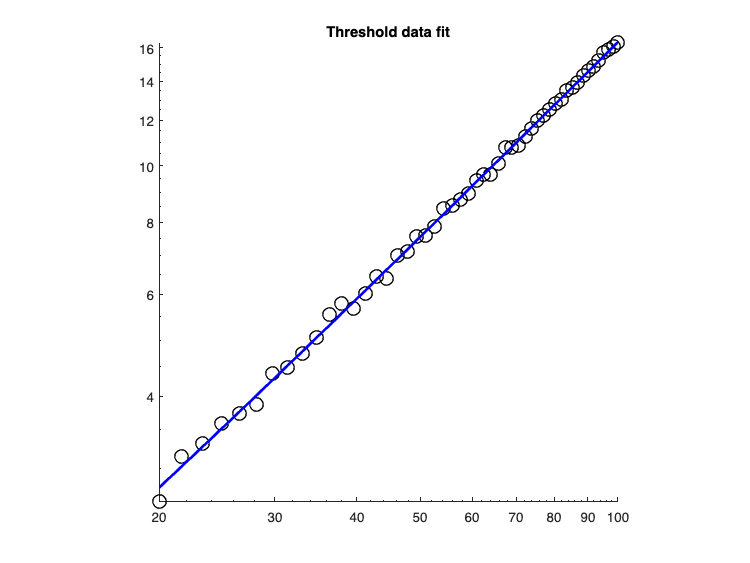

% Least-square fitting
loss_thresh = @(s, w, d, beta, dt) sum((log(mk_threshold(s, w, d, beta))- log(dt)).^2);

threshold_init = rand(1, 3); 

% fitting threshold data
f.thresh_prm = fminsearch(@(x) loss_thresh(s, x(1), x(2), x(3), threshold_dt), threshold_init);

% plot threshold fit
f.thresh_axis = linspace(min(s), max(s), 100);
f.thresh_prd  = mk_threshold(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3));

% plot the fit
figure (3), clf
loglog(s, threshold_dt, 'ko', 'markersize', 10, 'linewidth', 1), axis square, hold on
loglog(s, f.thresh_prd, 'b-', 'linewidth', 2), box off, title('Threshold data fit')

## Making predictions to intensity data

## model fit -- modulated Poisson

loss1 = @(s, d, w, beta, c, g, sc, dt) sum((mkPercept(s, d, w, beta, c, g, sc) - dt).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    % initiate model fitting with random seeds
    init = rand(1, 3) * 5;

    prm(k, :)= fminsearch(@(x) loss1(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), intensity_dt), init);

    % make model prediction
    prd(k, :) = mkPercept(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(k, 1), prm(k, 2), prm(k, 3));

    % compute r2
    r2(k) = compute_r2(intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.669338 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.004388 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.004486 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.009790 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.013614 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.753883 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

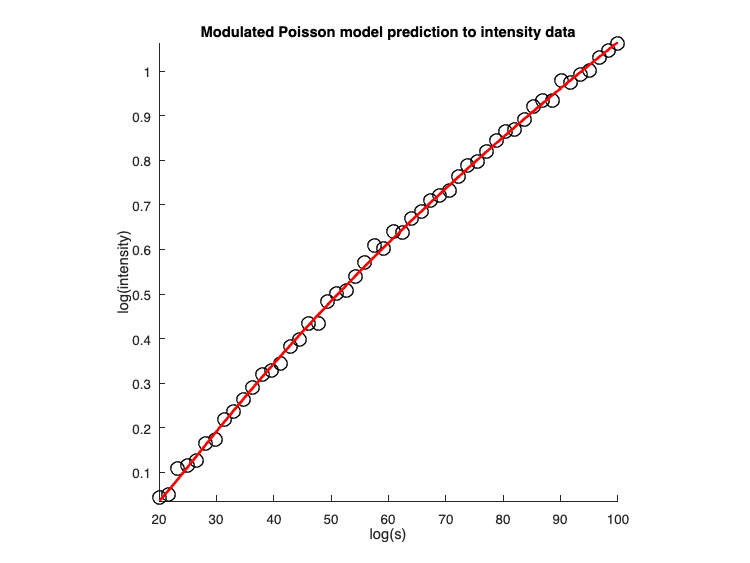


% choose the set of parameters that generate the best fitting outcomes
idx = find(r2 == max(r2));
f.perc_prm_fullmodel = prm(idx, :);
f.perc_prd_fullmodel = mkPercept(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_fullmodel(1), f.perc_prm_fullmodel(2), f.perc_prm_fullmodel(3));

% visualize the model fit
figure (4), clf
plot(s, intensity_dt, 'ko', 'markersize', 10, 'linewidth', 1), hold on
plot(s, f.perc_prd_fullmodel, 'r-', 'linewidth', 2), axis square, box off
title('Modulated Poisson model prediction to intensity data')
xlabel('log(s)'), ylabel('log(intensity)')

## model fit -- additive model

loss2 = @(s, d, w, beta, sigma, c, sc, dt) sum((mkPercept_additive(s, d, w, beta, sigma, c, sc) - dt).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 3) * 5; %[2, 50000, 20] + randn(1, 3);
    prm(k, :) = fminsearch(@(x) loss2(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), intensity_dt), init);

    % make model predictions
    prd(k, :) = mkPercept_additive(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2), prm(3));

    % compute r2
    r2(k) = compute_r2(s, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.515893 



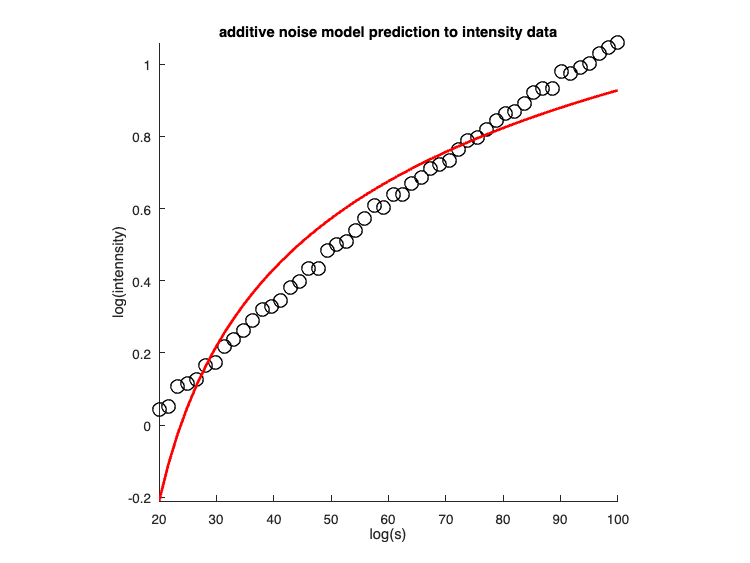


idx = find(r2 == max(r2));

f.perc_prm_additive = prm(idx, :);
f.perc_prd_additive = mkPercept_additive(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_additive(1), f.perc_prm_additive(2), f.perc_prm_additive(3));

figure (5), clf
plot(s, intensity_dt, 'ko', 'markersize', 10, 'linewidth', 1), hold on
plot(s, f.perc_prd_additive, 'r-', 'linewidth', 2), title('additive noise model prediction to intensity data'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

## model fit -- multiplicative model

loss3 = @(s, d, w, beta, c, g, sc, dt) sum((mkPercept_multiplicative(s, d, w, beta, c, g, sc) - dt).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 3) * 5;

    prm(k, :) = fminsearch(@(x) loss3(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), intensity_dt), init);

    % make model predictions
    prd(k, :) = mkPercept_multiplicative(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2), prm(3));

    % compute r2
    r2(k) = compute_r2(intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.014345 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.014345 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.015468 



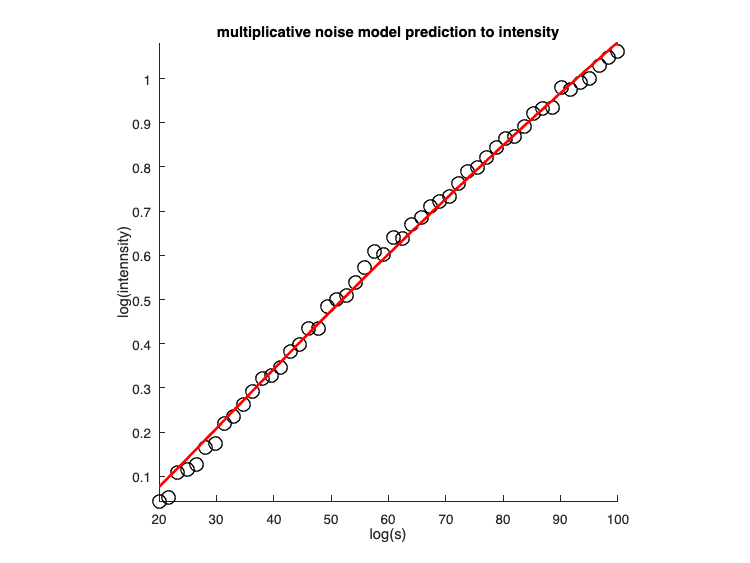


idx = find(r2 == max(r2));

f.perc_prm_multiplicative = prm(idx, :);
f.perc_prd_multiplicative = mkPercept_multiplicative(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_multiplicative(1), f.perc_prm_multiplicative(2), f.perc_prm_multiplicative(3));

figure (6), clf
plot(s, intensity_dt, 'ko', 'markersize', 10, 'linewidth', 1), hold on
plot(s, f.perc_prd_multiplicative, 'r-', 'linewidth', 2), title('multiplicative noise model prediction to intensity'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

## Poisson model

loss4 = @(s, d, w, beta, c, sc, dt) sum((mkPercept_poisson(s, d, w, beta, c, sc) - dt).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 2) * 20; % 10, 20

    prm(k, :) = fminsearch(@(x) loss4(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), intensity_dt), init);
    % make model predictions
    prd(k, :) = mkPercept_poisson(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2));

    % compute r2
    r2(k) = compute_r2(intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.678301 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.673514 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.670402 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.654373 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.669833 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4.664250 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

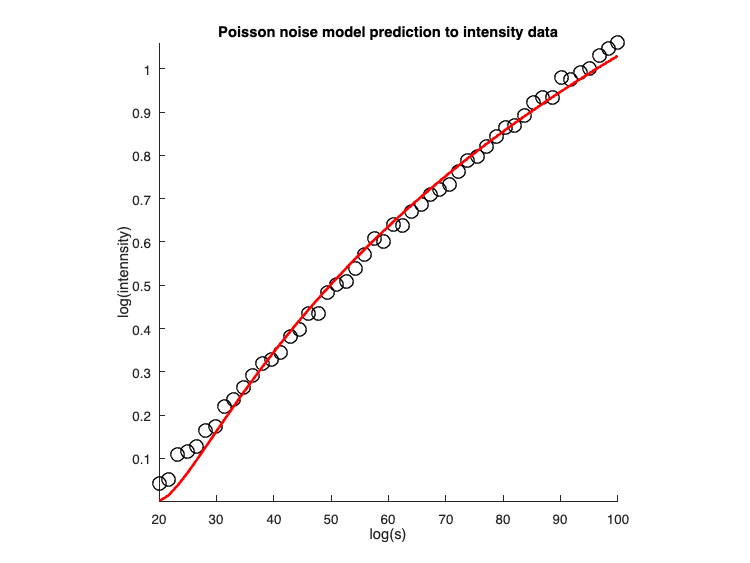


idx = find(r2 == max(r2));

f.perc_prm_poisson = prm(idx, :);
f.perc_prd_poisson = mkPercept_poisson(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_poisson(1), f.perc_prm_poisson(2));

figure (2), clf
plot(s, intensity_dt, 'ko', 'markersize', 10, 'linewidth', 1), hold on
plot(s, f.perc_prd_poisson, 'r-', 'linewidth', 2), title('Poisson noise model prediction to intensity data'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

## Noise models

function output = mkPercept(s, d, w, beta, c, g, sc)
% modualted Poisson model

% s: stimulus, a vector
% d: the first constant from perceptual threshold fit
% w: the second constant from perceptual threshold fit
% beta: the third constant from perceptual threshold fit
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted

step1 = w .* (d - s) + c .* (s - d).^beta;
step2 = g .* (s - d).^(-beta);
step3 = step1 .* step2 ./(2 * (beta - 1));
output = sinh(sc .* step3).^2./ (g.^2);
end

% additive noise model ---------------------------------------
function output = mkPercept_additive(s, d, w, beta, sigma, c, sc)

% s: stimulus, a vector
% d, w, beta: constants from perceptual threshold fit
% sigma; standard deviation of the internal representation, to be fitted
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted
step1 = w .* sigma .* (s - d).^(1-beta);
step2 = step1 ./(1-beta) + c;
output = sc .* step2;
end

% multiplicative noise model ---------------------------------

function output = mkPercept_multiplicative(s, d, w, beta, c, g, sc)

% all parameters are as stated in the previous two functions
step1 = g .* w .* (s - d).^(1-beta);
step2 = exp(step1 ./(1 - beta)) .* c;
output = sc .* step2;
end

% Poisson noise model ----------------------------------------

function output = mkPercept_poisson(s, d, w, beta, c, sc)

% all parameters are as previously stated
step1 = (w .* (d - s) + (beta - 1).* c .* (s - d).^beta) .^2;
step2 = (s - d).^(-2 .* beta) .* step1;
output = sc .* step2 ./ (4 .* (beta - 1).^2);
end

% compute r2 -------------------------------------------------
function r2 = compute_r2(data, prd)

r2 =  1 - (sum((data - prd).^2))./(sum((prd - mean(prd)).^2));

end
